## AAE334 HW12 P1

clear all; close all; clc;
fdir = 'C:\Users\Tomo\Desktop\studies\2020-Spring\AAE334\matlab\outputs\HW12';
set(groot, 'defaulttextinterpreter',"latex");
set(groot, 'defaultAxesTickLabelInterpreter',"latex");
set(groot, 'defaultLegendInterpreter',"latex");

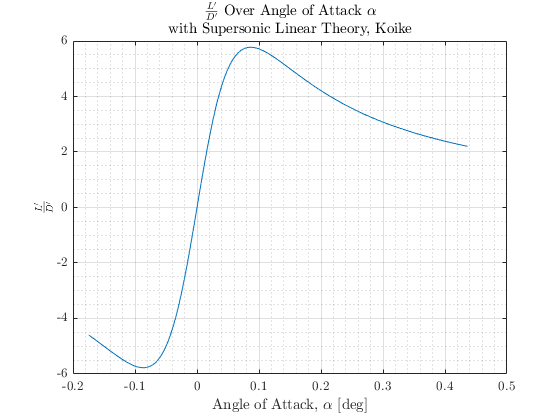

% Plotting
a = deg2rad(-10:0.0001:25);
Lp_Dp = a./(a.^2 + 0.0075);

fig = figure("Renderer","painters");
    plot(a,Lp_Dp);
    title({'$\frac{L^{\prime}}{D^{\prime}}$ Over Angle of Attack $\alpha$', ['' ...
        'with Supersonic Linear Theory, Koike']});
    xlabel('Angle of Attack, $\alpha$ [deg]')
    ylabel('$\frac{L^{\prime}}{D^{\prime}}$')
    grid on; grid minor; box on;
saveas(fig,fullfile(fdir,'lift2dragRatio.png'));


% Maximum value 
Lp_Dp_max = max(Lp_Dp)

Lp_Dp_max = 5.7735